# Lab 4

## Problem 1

In this problem we are looking at the data from a gamma-ray satellite orbiting in low Earth orbit. It takes a reading of the number of particles detected every 100 milliseconds, and is in an approximately 90 minute orbit. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays. Metadata is incorporated in the data file. 

1) Down load the data from the course website (gammaray_lab4.h5), and import it into your working environment. The data has 4 columns and more than 25 million rows. The columns are time (in gps seconds), Solar phase (deg) showing the position of the sun relative to the orbit, Earth longitude (deg) giving the position of the spacecraft relative to the ground, and particle counts. Make a few plots, generally exploring your data and making sure you understand it. Give a high level description of the data features you see. Specifically comment on whether you see signal contamination in your data, and how you plan to build a background pdf().

Importing data...

h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:);

Columns = time, solar phase, earth longitude, counts

see how counts are changing with each variable

time = mydata(:,1);
solphase = mydata(:,2);
earthlong = mydata(:,3);
counts = mydata(:,4);

#### *Basic Plots of Each Variable Versus Time:*

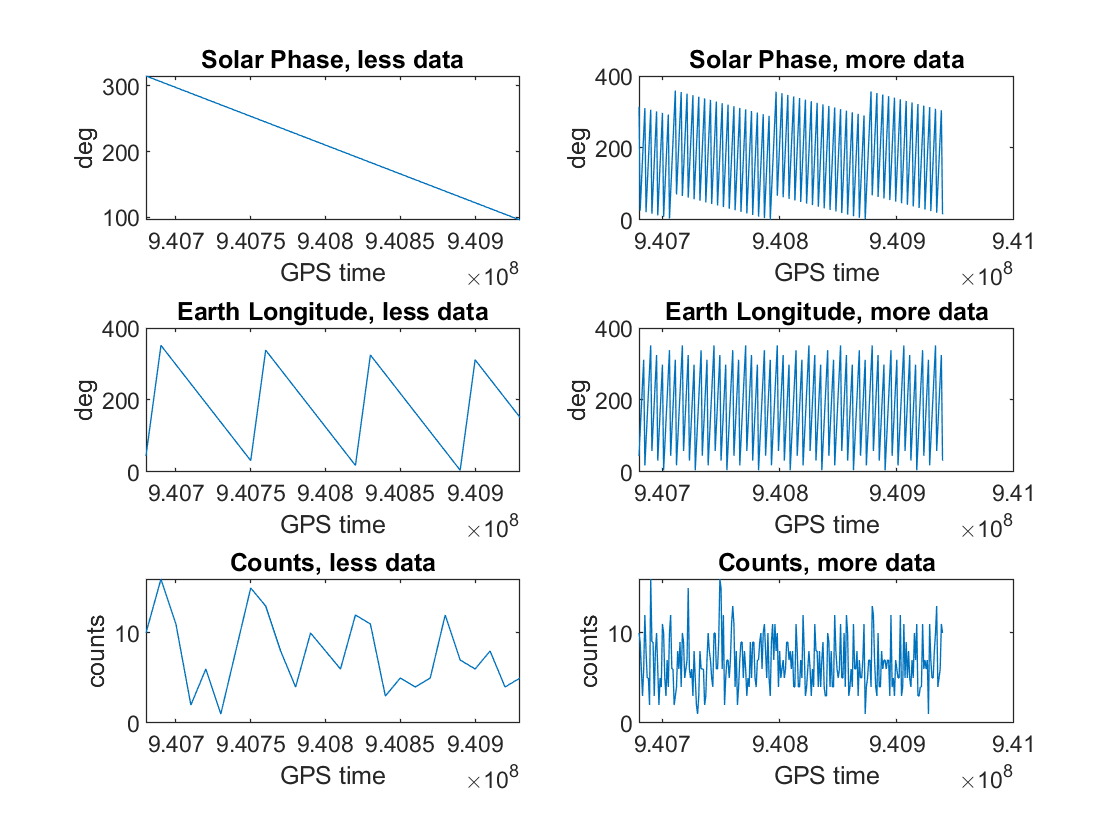

smallsp = (1:100000:2592001);
widesp = (1:10000:2592001);
subplot(3,2,1)
plot(time(smallsp),solphase(smallsp))
title('Solar Phase, less data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,2)
plot(time(widesp),solphase(widesp))
title('Solar Phase, more data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,3)
plot(time(smallsp),earthlong(smallsp))
title('Earth Longitude, less data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,4)
plot(time(widesp),earthlong(widesp))
title('Earth Longitude, more data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,5)
plot(time(smallsp),counts(smallsp))
title('Counts, less data')
xlabel('GPS time')
ylabel('counts')
subplot(3,2,6)
plot(time(widesp),counts(widesp))
title('Counts, more data')
xlabel('GPS time')
ylabel('counts')

*Observations:*

- Solar phase and Earth longitude graphs are uniform and appear to be periodic. 

- Counts vs. time graph is random. There doesn't appear to be a direct correlation between counts and time. 

- No obvious outliers looking at these graphs (though they don't contain all of the data). Taking a look at maxima and minima and comparing to these graphs will give a better understanding of outliers. 

*Maxima and minima: *

maxsp = max(solphase)

maxsp = 360.0000

minsp = min(solphase)

minsp = 6.9942e-06

maxel = max(earthlong)

maxel = 359.9933

minel = min(earthlong)

minel = 0

maxc = max(counts)

maxc = 30

minc = min(counts)

minc = 0

Comparing these values to my graphs, it seems the solar phase has no outliers, since the maximum and minimum values are within the uniform periodic values seen in the "more data" plot. 

Similarly, Earth longitude's maximum and minimum values are consistent with its plot. 

The maximum for counts is more out there; however, 30 counts is feasible. It's not orders of magnitude above the other data points. From the "more data" plot, the counts values seem to hover around 6. For comparison, I'll check the average of all the counts data: 

avgcounts = mean(counts)

avgcounts = 7.0973

n30 = find(counts>29);
num30 = length(n30)

num30 = 3

The average counts is about 7, so 30 is far above the average. Also, there are only 3 occurrences of 30 counts in the entire data set, so a measurement of 30 counts is far above average. 

p = num30/length(counts);
sigma = norminv(p)

sigma = -5.1721

The sigma of measuring 30 counts is above 5, so it is significant. However, there are only 3 such measurements out of millions, so they shouldn't influence my background. 

#### *Counts vs. Other Stuff (Histograms):*

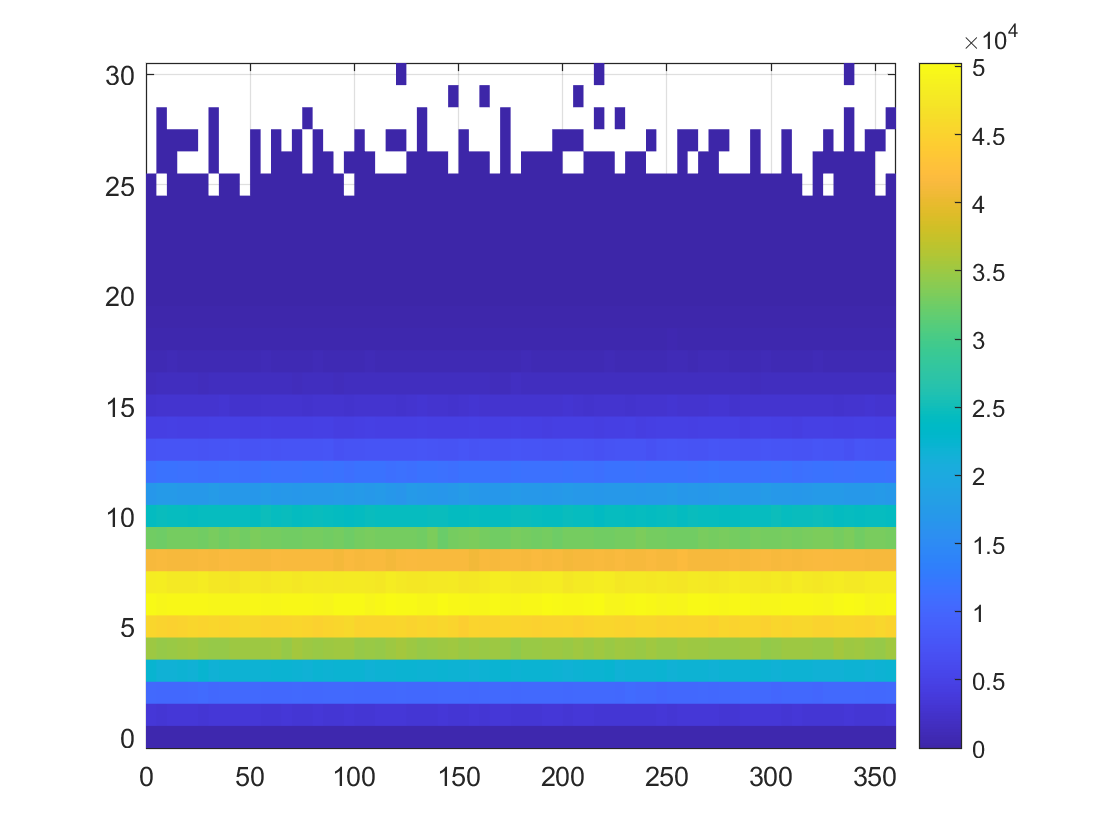

subplot(1,1,1)
histogram2(solphase,counts,'DisplayStyle','tile')
colorbar

Counts and solar phase seem to be independent of each other. The graph shows a perfectly uniform gradient, so counts don't change at all with changes in solar phase. 

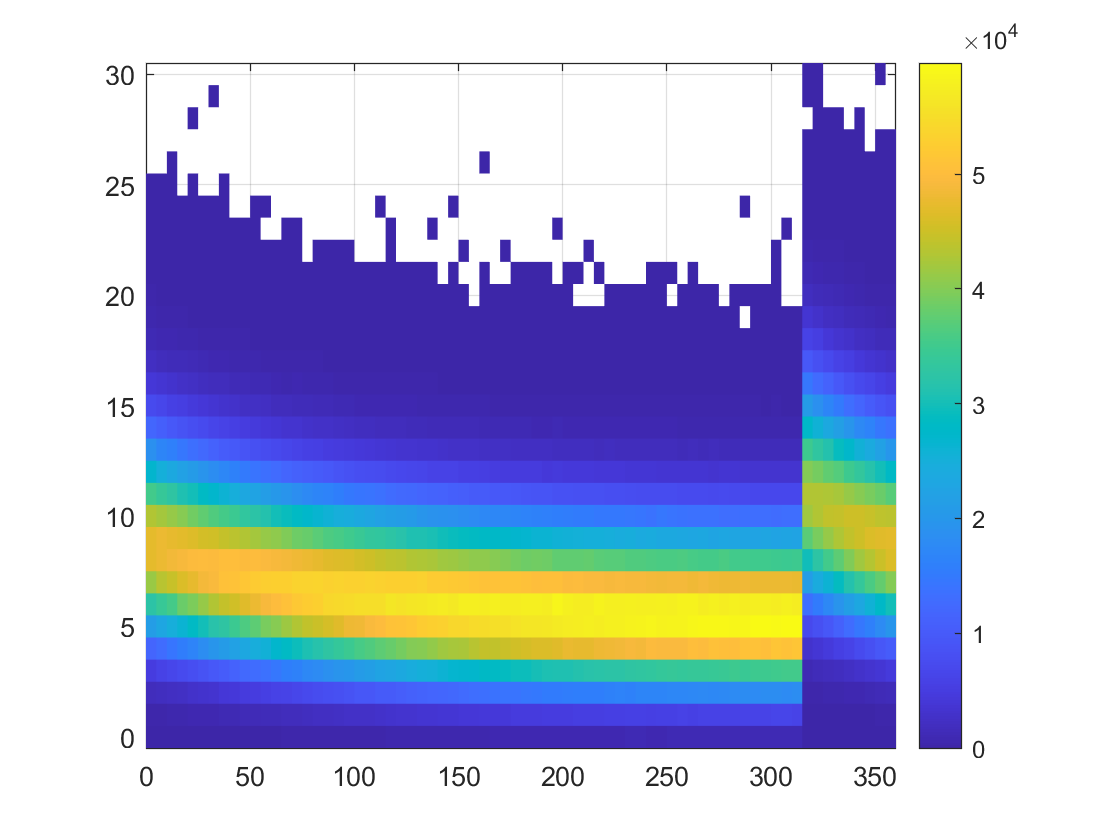

subplot(1,1,1)
histogram2(earthlong,counts,'DisplayStyle','tile')
colorbar

There's a correlation between counts and Earth longitude. In the graph, there's a distinct jump around 315-325 degrees. Since the longitude appears to be periodic with time, the start of the 'period' may not be 0. Judging by the graph, it starts at that jump. Considering the > 320 region to the left of 0, there appears to be some form of decay, with a sharp decline early on that flattens out to a straight line. 

For our background, we should therefore consider how the distribution of counts changes within a period of Earth longitude data. 

*Histograms of counts:*

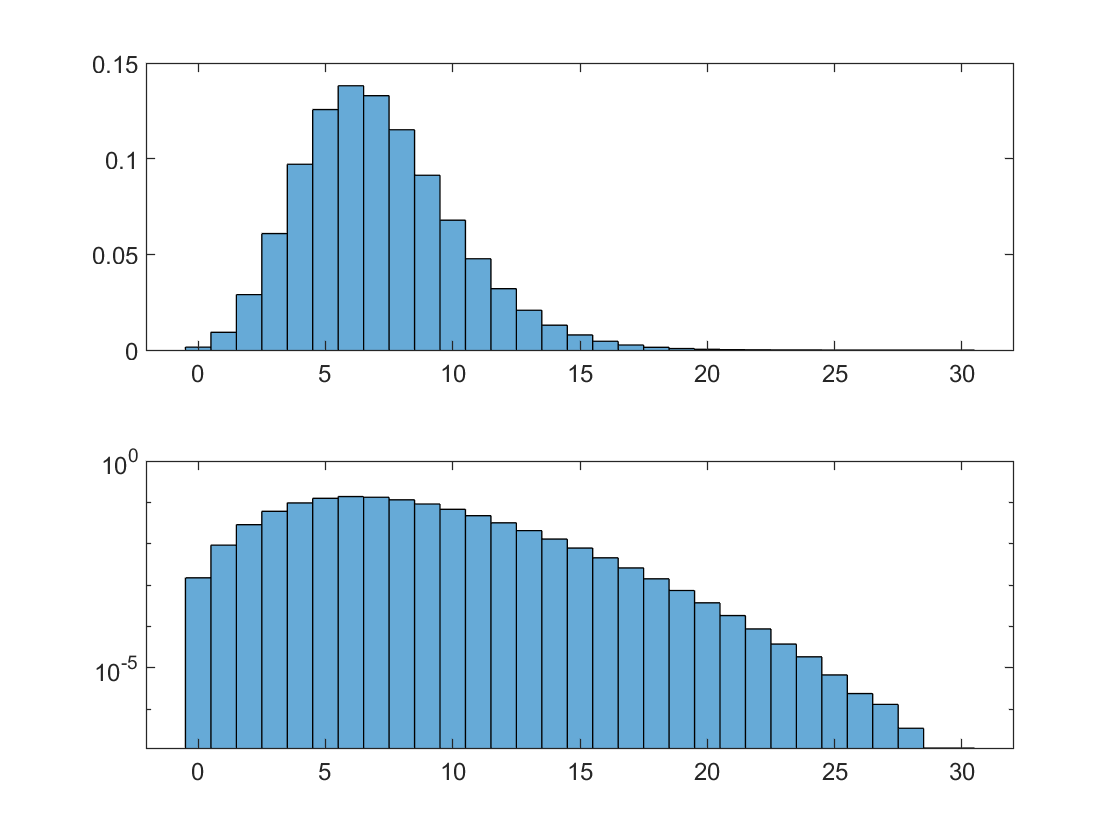

subplot(2,1,1)
histogram(counts,'Normalization','pdf')
subplot(2,1,2)
histogram(counts,'Normalization','pdf')
set(gca,'Yscale','log')


lambda = mean(counts);

Looking at these histograms, the distribution of counts looks like a Poisson distribution. I've assigned 'lambda' to the mean to use in generating a Poisson distribution for comparison.

*Overlay with Poisson:*

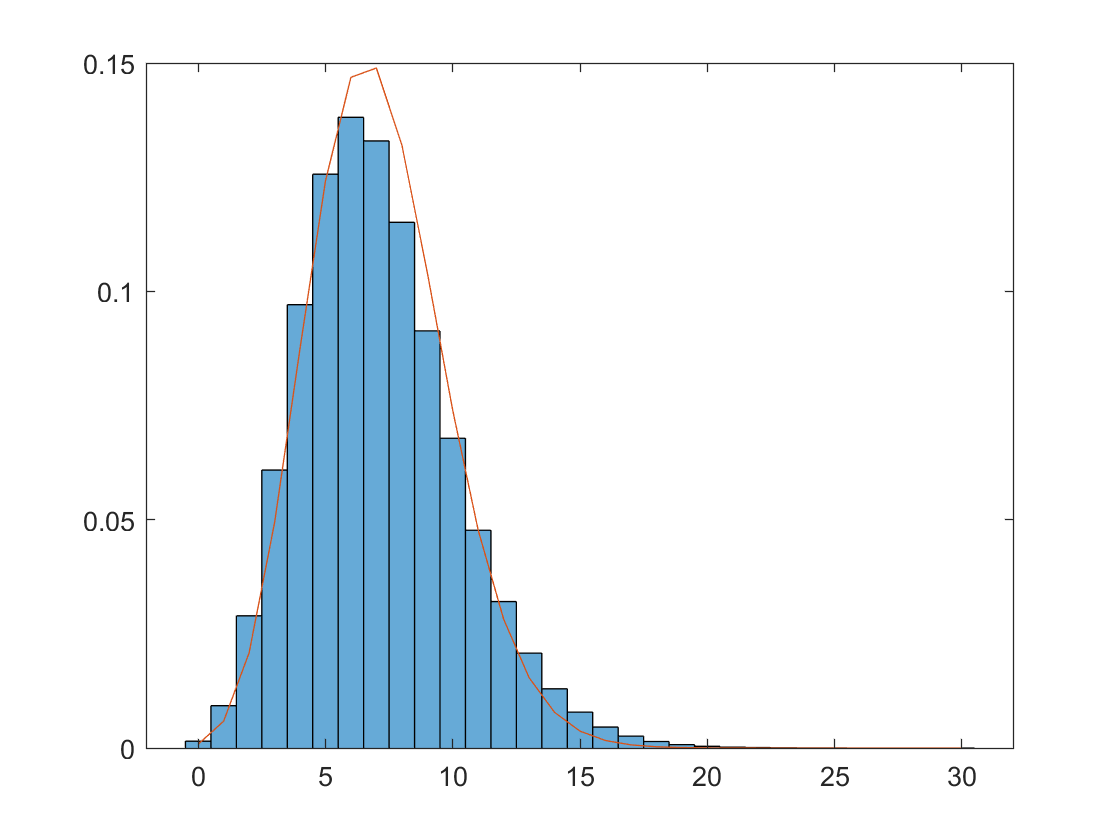

subplot(1,1,1)
histogram(counts,'Normalization','pdf')
hold on
xes = 0:1:30;
pd = makedist('Poisson','lambda',lambda);
plot(xes,pdf(pd,xes),'LineWidth',2)
hold off

The overlay matches the histogram fairly well, so I'm confident in using a Poisson distribution for my background. 

2) The background is **not** consistent across the dataset. Find and describe as accurately as you can how the background changes.

Background changes with earth longitude, as seen in the graph above

- take sections and plot counts background distribution for that segment

- see how condition shifts 

- 2592001 data points

- compare 1000 data point intervals @start, some in middle, end

- plot means

% c1 = mydata(1:1000,4);
% 
% c2 = mydata(648001:649000,4);
% 
% c3 = mydata(1296001:1297000,4);
% 
% c4 = mydata(2591002:2592001,4);
% 
% subplot(4,1,1)
% histogram(c1,'Normalization','pdf')
% subplot(4,1,2)
% histogram(c2,'Normalization','pdf')
% subplot(4,1,3)
% histogram(c3,'Normalization','pdf')
% subplot(4,1,4)
% histogram(c4,'Normalization','pdf')
% 
% l1 = mean(c1)
% l2 = mean(c2)
% l3 = mean(c3)
% l4 = mean(c4)

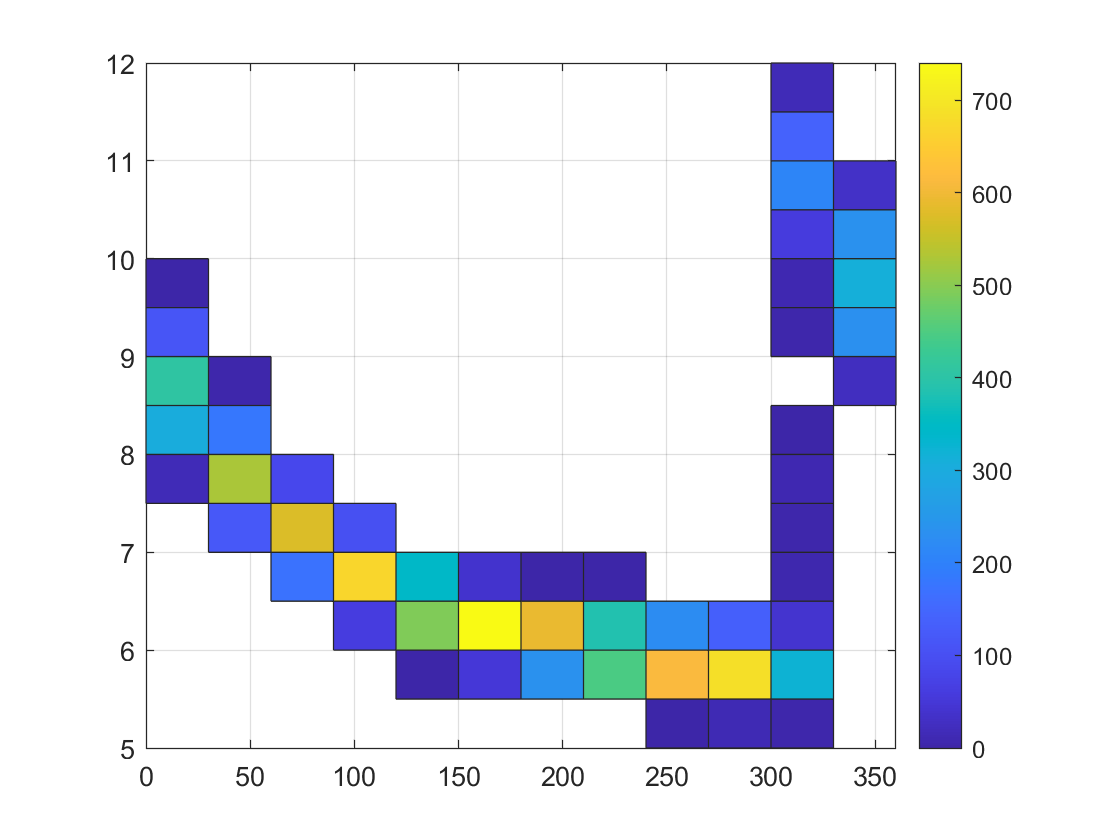

cmeans = zeros(10008,1);

for i = 0:10007
    cmeans(i+1,1) = mean(mydata((259*i+1):(259*(i+1)),4));
end

elpoints = mydata(1:259:2592001,3);

subplot(1,1,1)
histogram2(elpoints,cmeans,'DisplayStyle','tile')
colorbar

OBSERVATIONS

- means follow counts vs el

3) Create a model for the background that includes time dependence, and explicitly compare your model to the data. How good is your model of the background?

- earth longitude is time dependent (periodic function)

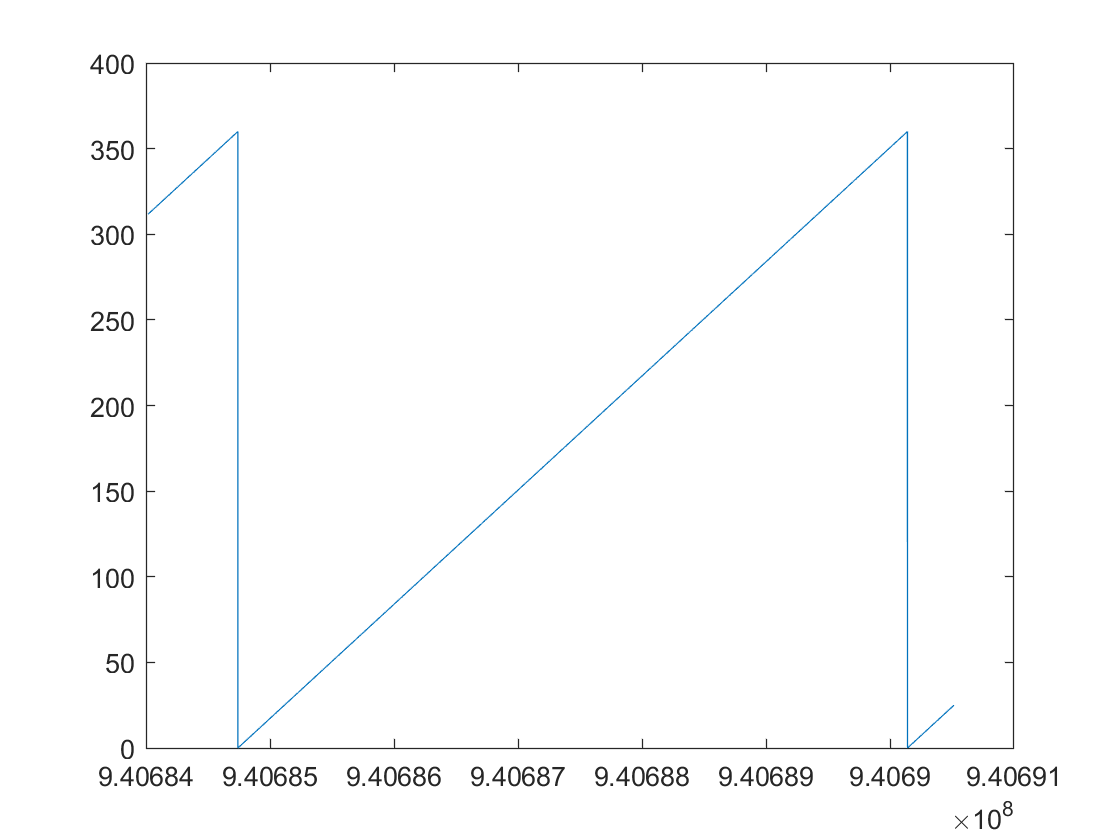

subplot(1,1,1)
plot(time(40000:105000),earthlong(40000:105000))

So one period for earthlong is about t = 5500

some graphs of distributions in one period:

t = 9.40685 --> t = 9.40686

and

t = 9.40689 --> t = 9.40690

4) Because the background varies, your discovery sensitivity threshold (how many particles you would need to see) also varies. What is the '5-sigma' threshold for a 100 millisecond GRB at different times?

## Problem 2

In this problem we are going to look at a stack of telescope images (again simulated). We have 10 images, but you and your lab partner will be looking for different signals. One of you will be looking for the faintest stars, while the other will be looking for a transient (something like a super novae that only appears in one image). Flip a coin to determine which of you is pursuing which question.

1) Dowload the data from `images.h5`. This is a stack of 10 square images, each 200 pixels on a side.

h5disp('images.h5')

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


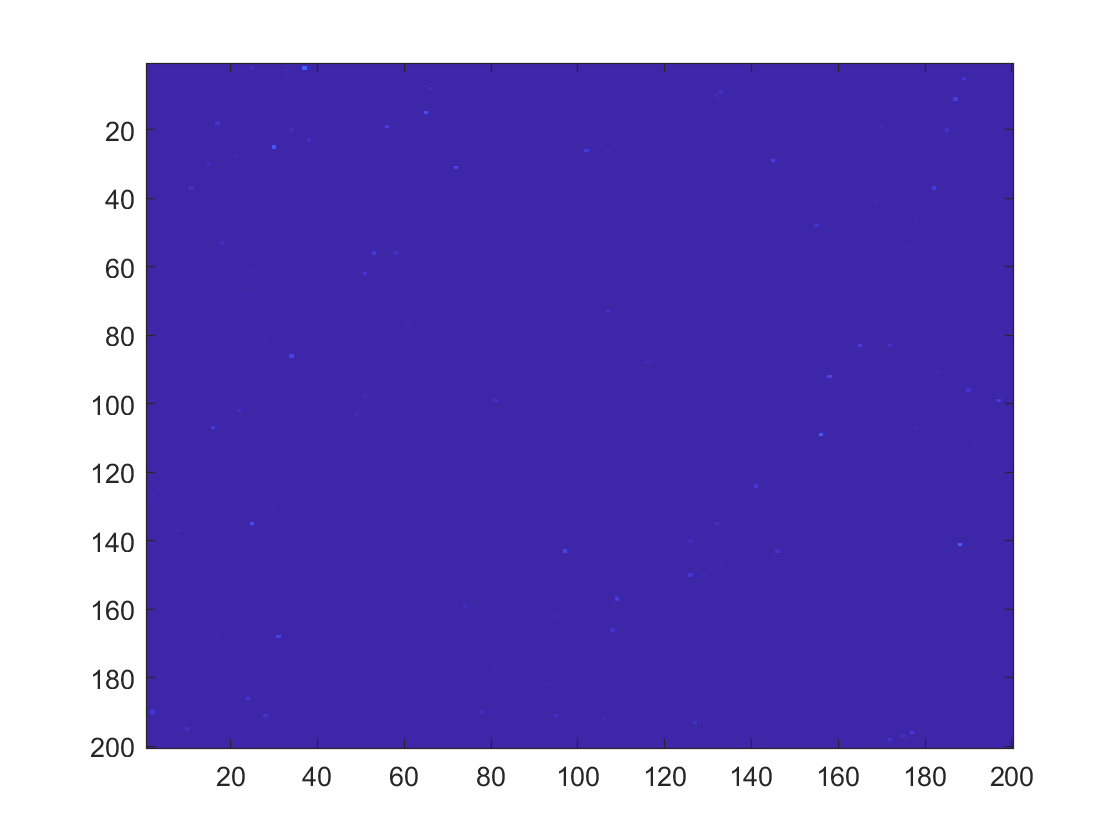

image1 = h5read('images.h5','/image1');
image(image1)

imagestack = h5read('images.h5','/imagestack');

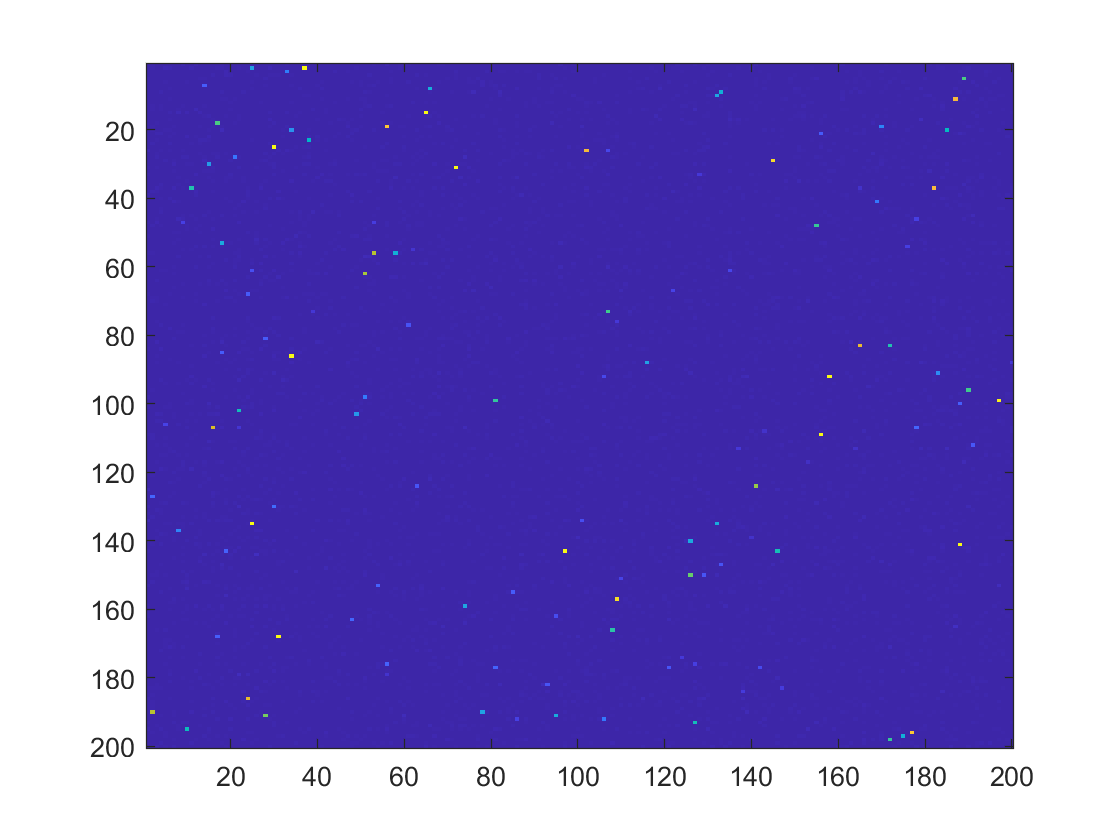

stack = zeros(200,200);

for k = 1:200
    for j = 1:200
        stack(k,j) = sum(imagestack(:,k,j));
    end
end

image(stack)

2) Explore the data. Is there signal contamination? Is the background time dependent? Is it consistent spatially? Develop a plan to calculate your background pdf().

To calculate background pdf, 

- compress each individual image into a 1D background, average, plot 1D

- plot every pixel brightness (put all rows into a single column vector)

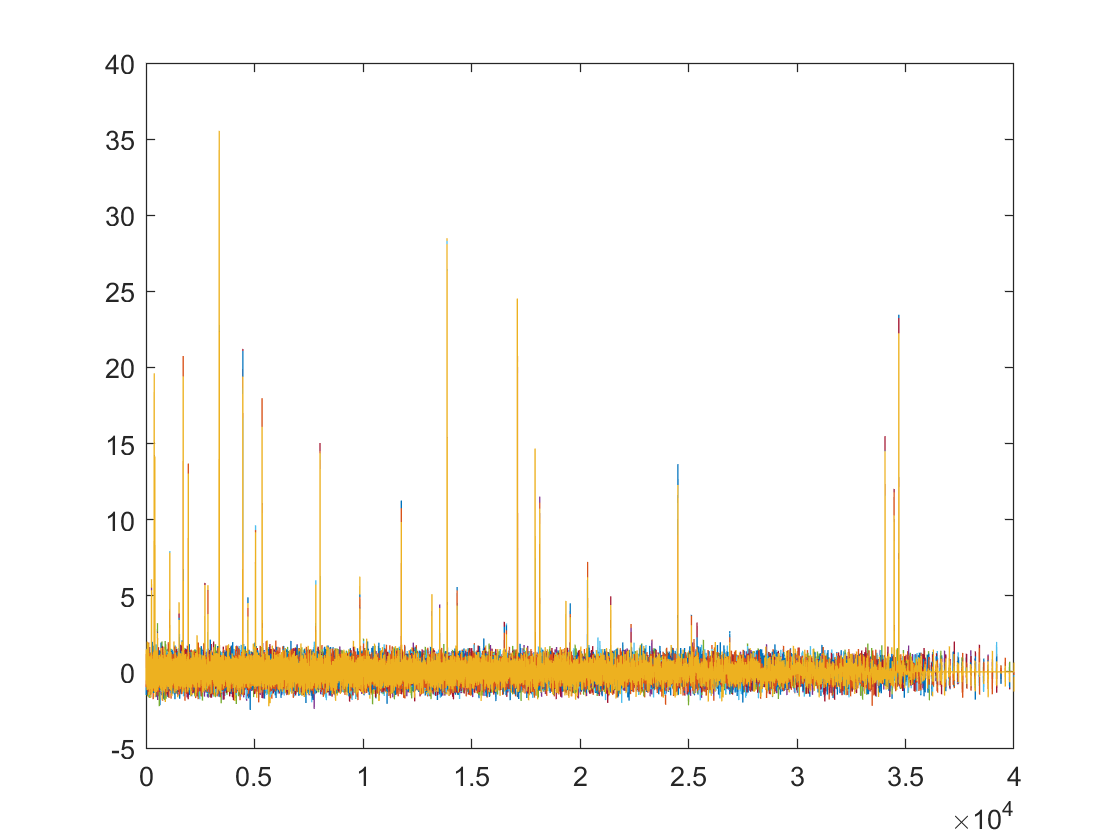

brightness = zeros(10,40000);

for b = 1:10
    for i = 1:200
        for h = 1:200
            brightness(b,i*h) = imagestack(b,i,h);
        end
    end
end

x = 1:40000;
brightness1 = brightness(1,:);
plot(x,brightness1)
hold on
for i = 2:10
    plot(x,brightness(i,:))
end
hold off

- background is just the static-y stuff, peaks are stars

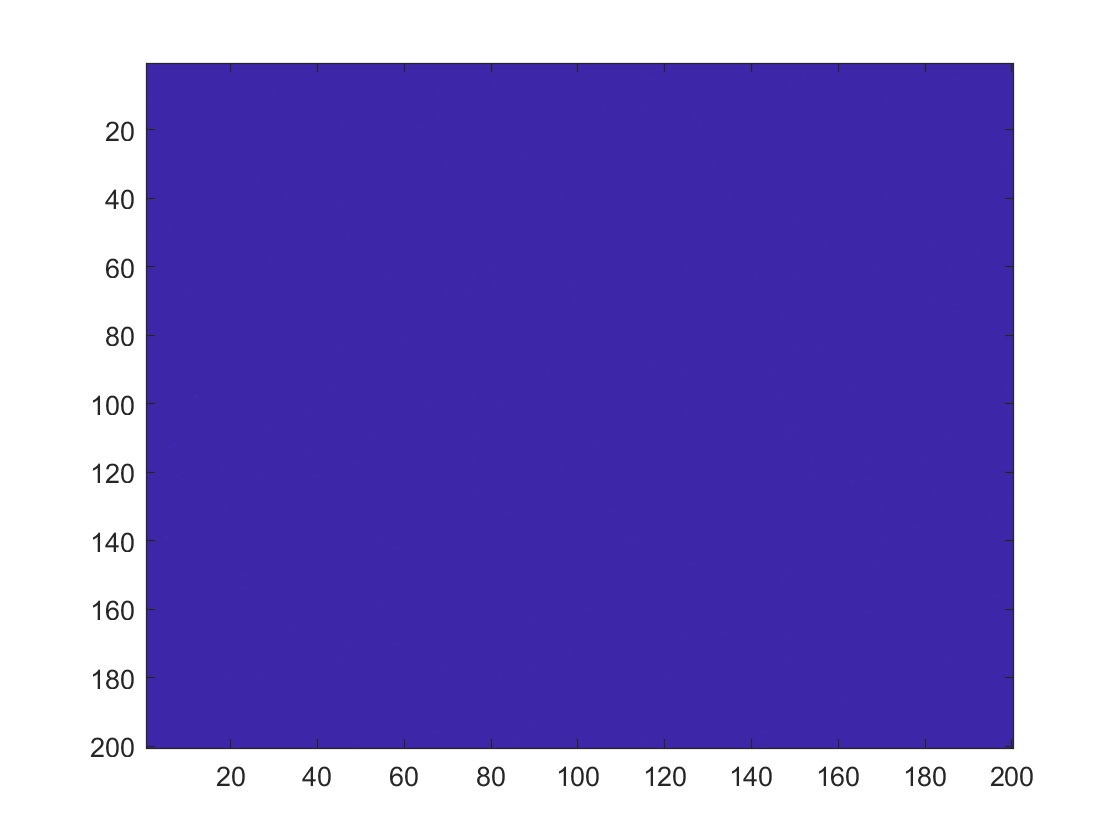

firstlast = zeros(200,200);

for m = 1:200
    for n = 1:200
        firstlast(m,n) = imagestack(1,m,n) - imagestack(10,m,n);
    end
end
image(firstlast)

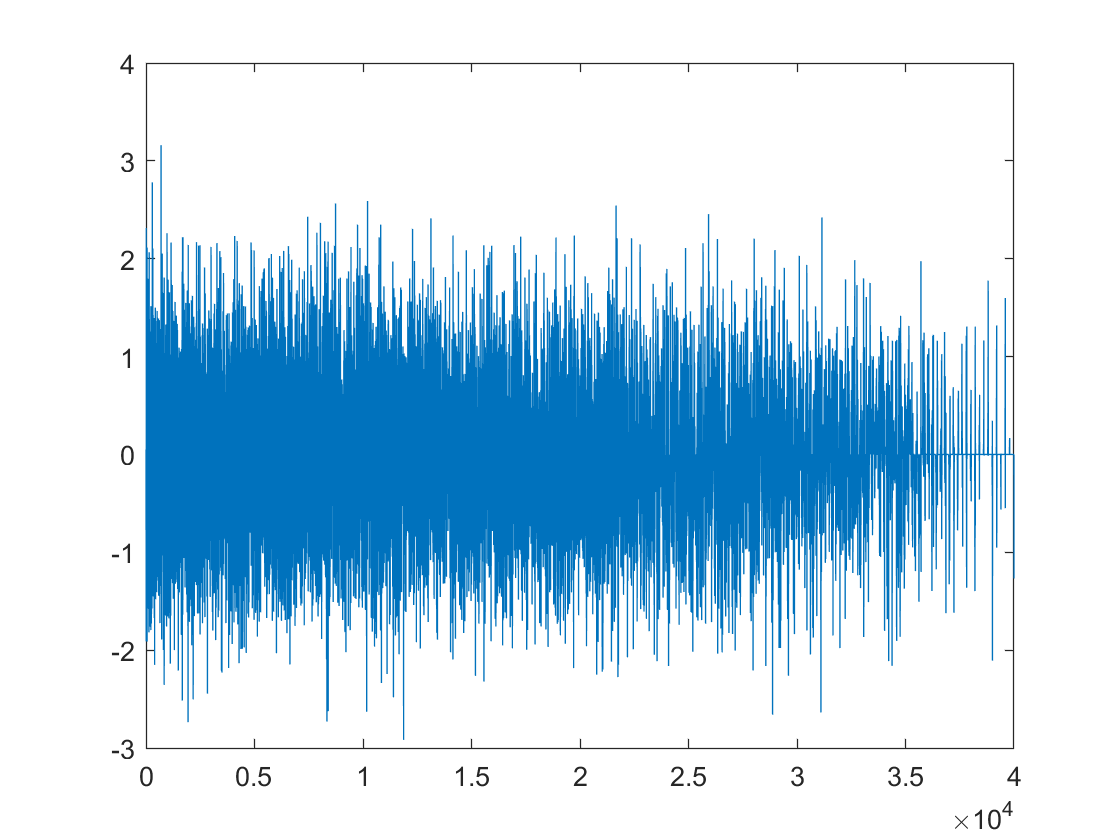

diff = zeros(1,40000);

for i = 1:200
    for h = 1:200
        diff(1,i*h) = firstlast(i,h);
    end
end

subplot(1,1,1)
plot(x,diff)

% averaged = zeros(1,200);
% 
% for p = 1:200
%     averaged(1,p) = sum(stack(:,p));
% end
% 
% averaged = averaged/200;
% x = 1:200;
% subplot(1,1,1)
% plot(x,averaged)

3) Using your background distribution, hunt for your signal (either faint stars, or a transient). Describe what you find.

Looking for a transient. 

- greatest difference between images?

changes = zeros(9,40000);

for r = 1:9
    changes(r,:) = abs(brightness(r,:) - brightness(r+1,:));
end

onetwo = max(changes(1,:))

onetwo = 2.9466

twothree = max(changes(2,:))

twothree = 3.1888

threefour = max(changes(3,:))

threefour = 4.1681

fourfive = max(changes(4,:))

fourfive = 2.9873

fivesix = max(changes(5,:))

fivesix = 3.0461

sixseven = max(changes(6,:))

sixseven = 4.0703

seveneight = max(changes(7,:))

seveneight = 3.2980

eightnine = max(changes(8,:))

eightnine = 3.2869

nineten = max(changes(9,:))

nineten = 3.1060


x = 1:40000;
plot(x,brightness(3,:))
hold on
plot(x,brightness(4,:))
xlim([0.5*10^4,10000])

[M,I] = max(changes(3,:))

M = 4.1681

I = 7748

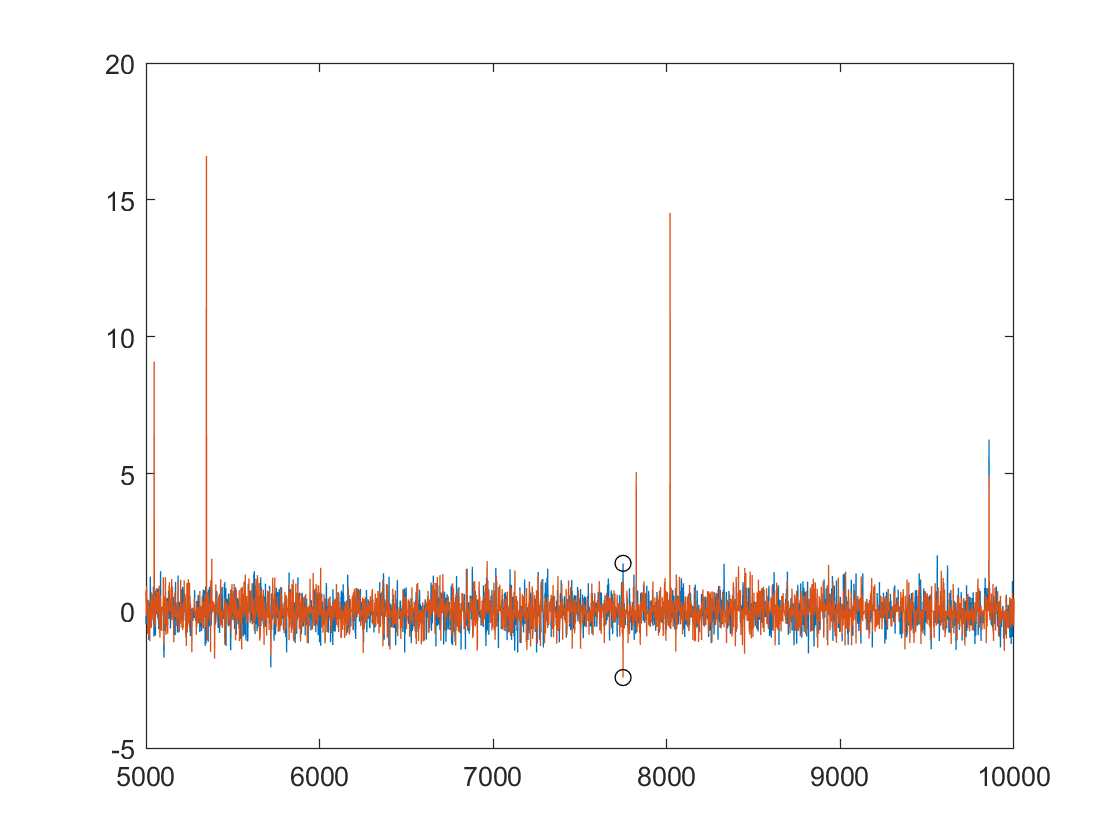


plot(I,brightness(4,I),'-o','Color','black')
plot(I,brightness(3,I),'-o','Color','black')
hold off

[N,J] = max(changes(7,:))

N = 3.2980

J = 21276

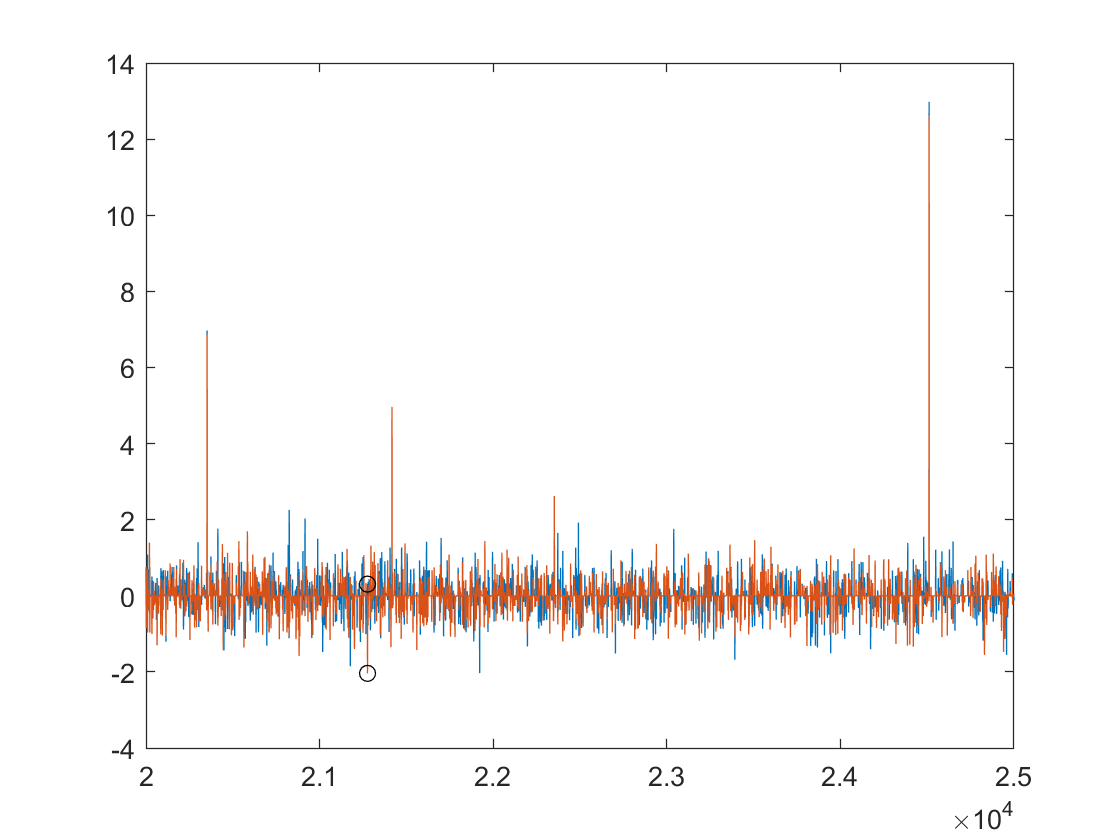

plot(x,brightness(6,:))
hold on
plot(x,brightness(7,:))
xlim([20000,25000])
plot(J,brightness(6,J),'-o','Color','black')
plot(J,brightness(7,J),'-o','Color','black')
hold off

4) You and your lab partner had different pdf(), but were using the *same* data. Explore why this is.